assert(endsWith(pwd, "non-ferromagnetic metal disk in frequency domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Uniform Grid

#### Electromagnet

EM.num = 2;
EM.inner_radius = [3.75e-3 7.75e-3]; % (m)
EM.outer_radius = [6.00e-3 10.00e-3]; % (m)
EM.length       = [4.00e-3 4.00e-3]; % length (m)
EM.Nturns = [60 60];

EM.z = [5.00e-3 5e-3]; % (m)

#### Sensor

Sensor.num = 10;
Sensor.side_length = 0.8e-3;

Sensor.position = [linspace(6e-3,30e-3,Sensor.num); 2.5e-3*ones(1,Sensor.num)];

#### Model

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 30; % number of elements in r direction
disk.n_z = 10; % number of elements in z direction

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildModel2D('Cylinder', r,z);

build model took 0.02 seconds


clear disk r z

Model.conductivity = 7.407e5 * ones(1,Model.num_elms); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, EM);

build governing equation took 55.39 seconds


#### Solve in frequency domain

EM.frequency_domain.current = [1 -1]; % (A)
EM.frequency_domain.current_density = EM.frequency_domain.current .* EM.Nturns ./ ((EM.outer_radius-EM.inner_radius).*EM.length); % (A/m^2)
EM.frequency_domain.frequency = 20000; % (Hz)

[Model, EM, Sensor] = SolveFrequencyDomain2D(GoverningEquation, Model, EM, Sensor);

solve current density took 0.02 seconds
solve magnetic flux density took 12.35 seconds


#### Plot result

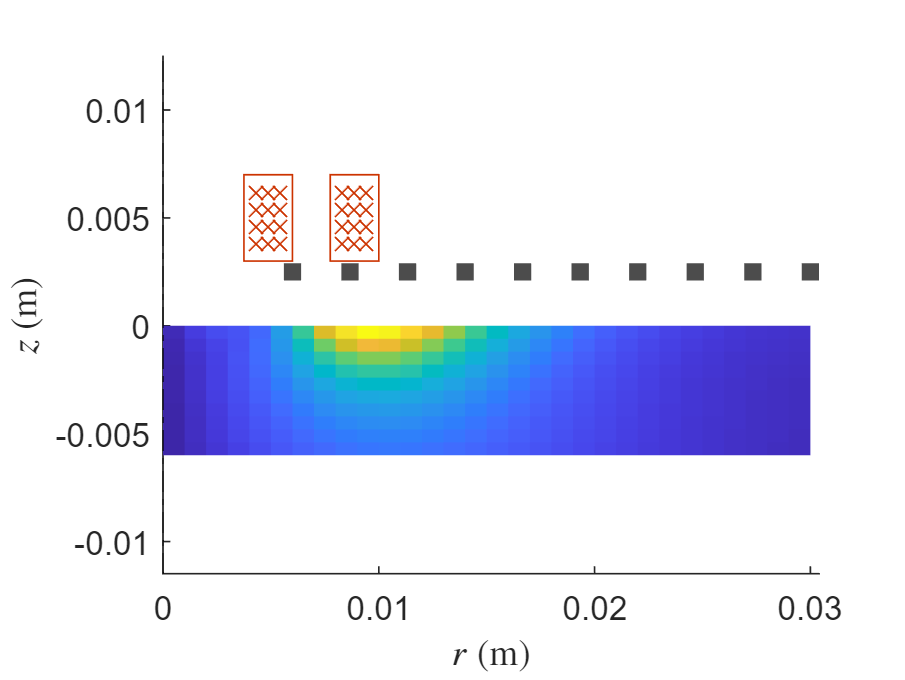

PlotWorld2D(Model, EM, Sensor, abs(Model.frequency_domain.J));

clf